% Initialization
close all
clear
clc

% Symbolic variables
syms x y r theta t real
syms u w beta real positive
syms pi

% Parameters
mu=1; epsilon_1=1.5^2; epsilon_2=1; k=2*pi; omega=k; a=3/4;

% Functions
u=a*sqrt(+(epsilon_1*k^2-beta^2));
w=a*sqrt(-(epsilon_2*k^2-beta^2));

% Equation
eqn=besselj(1,u)/(u*besselj(0,u))+...
    besselk(1,w)/(w*besselk(0,w))==0

$$eqn = \frac{4\,J_{1}\left(\frac{3\,\sqrt{9\,\pi^{2}-\beta^{2}}}{4}\right)}{3\,\sqrt{9\,\pi^{2}-\beta^{2}}\,J_{0}\left(\frac{3\,\sqrt{9\,\pi^{2}-\beta^{2}}}{4}\right)}+\frac{4\,K_{1}\left(\frac{3\,\sqrt{\beta^{2}-4\,\pi^{2}}}{4}\right)}{3\,K_{0}\left(\frac{3\,\sqrt{\beta^{2}-4\,\pi^{2}}}{4}\right)\,\sqrt{\beta^{2}-4\,\pi^{2}}}=0$$


% Solve
beta0=sqrt(2)/2*sqrt(epsilon_1+epsilon_2)*k;
beta=vpasolve(eqn,beta,beta0)

$$beta = 8.4136459074368151724482519761807$$


% Evaluate
pi=3.141592653589793;
if not(isnumeric(a))
  a=eval(a)
end
u=eval(eval(u))

u = 3.1852

w=eval(eval(w))

w = 4.1967

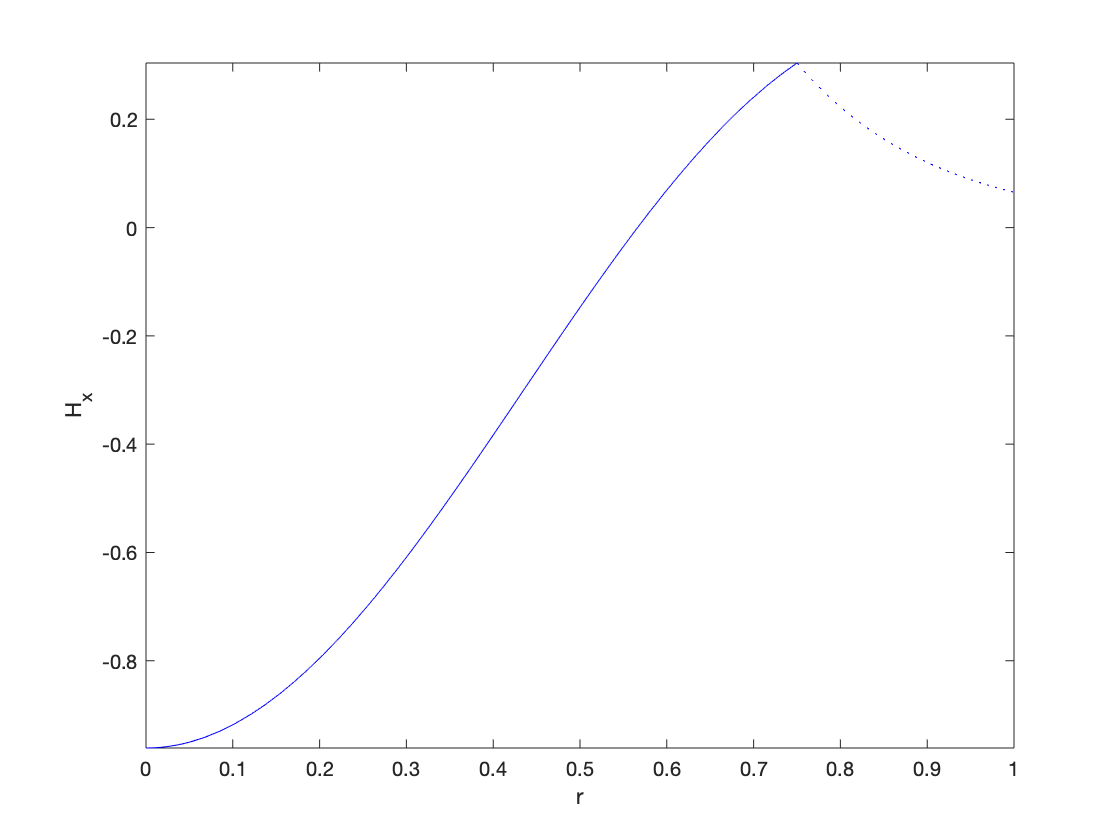


% Electromagnetic solution
H_x_1    =                                    besselj(0,u/a*r)*cos(omega*t-beta*x);
H_x_2    =          besselj(0,u)/besselk(0,w)*besselk(0,w/a*r)*cos(omega*t-beta*x);
H_r_1    =-beta*a/u                          *besselj(1,u/a*r)*sin(omega*t-beta*x);
H_r_2    =+beta*a/w*besselj(0,u)/besselk(0,w)*besselk(1,w/a*r)*sin(omega*t-beta*x);
E_theta_1=   +k*a/u                          *besselj(1,u/a*r)*sin(omega*t-beta*x);
E_theta_2=   -k*a/w*besselj(0,u)/besselk(0,w)*besselk(1,w/a*r)*sin(omega*t-beta*x);

% Plot
figure;
fplot(subs(H_x_1    ,[x,t],[1/2,1/8]),[0,a],'b-'); hold on;
fplot(subs(H_x_2    ,[x,t],[1/2,1/8]),[a,1],'b:'); xlabel('r'); ylabel('H_x');

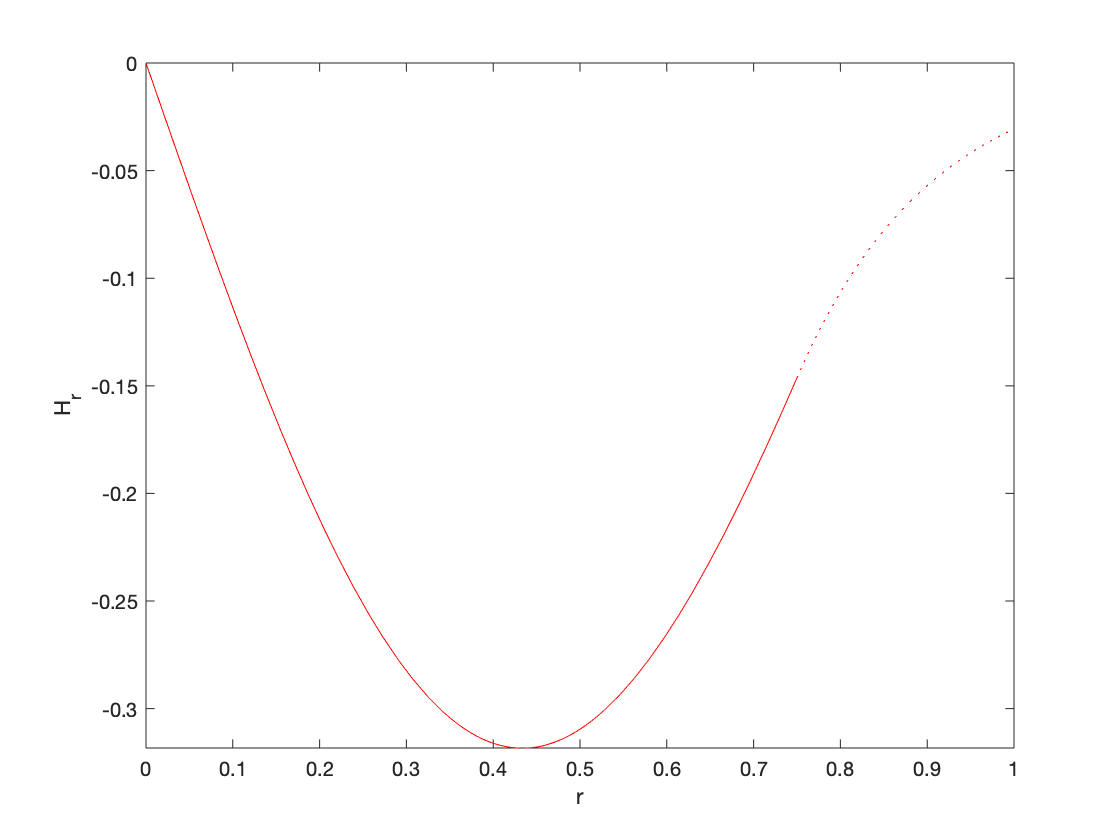

figure;
fplot(subs(H_r_1    ,[x,t],[1/2,1/8]),[0,a],'r-'); hold on;
fplot(subs(H_r_2    ,[x,t],[1/2,1/8]),[a,1],'r:'); xlabel('r'); ylabel('H_r');

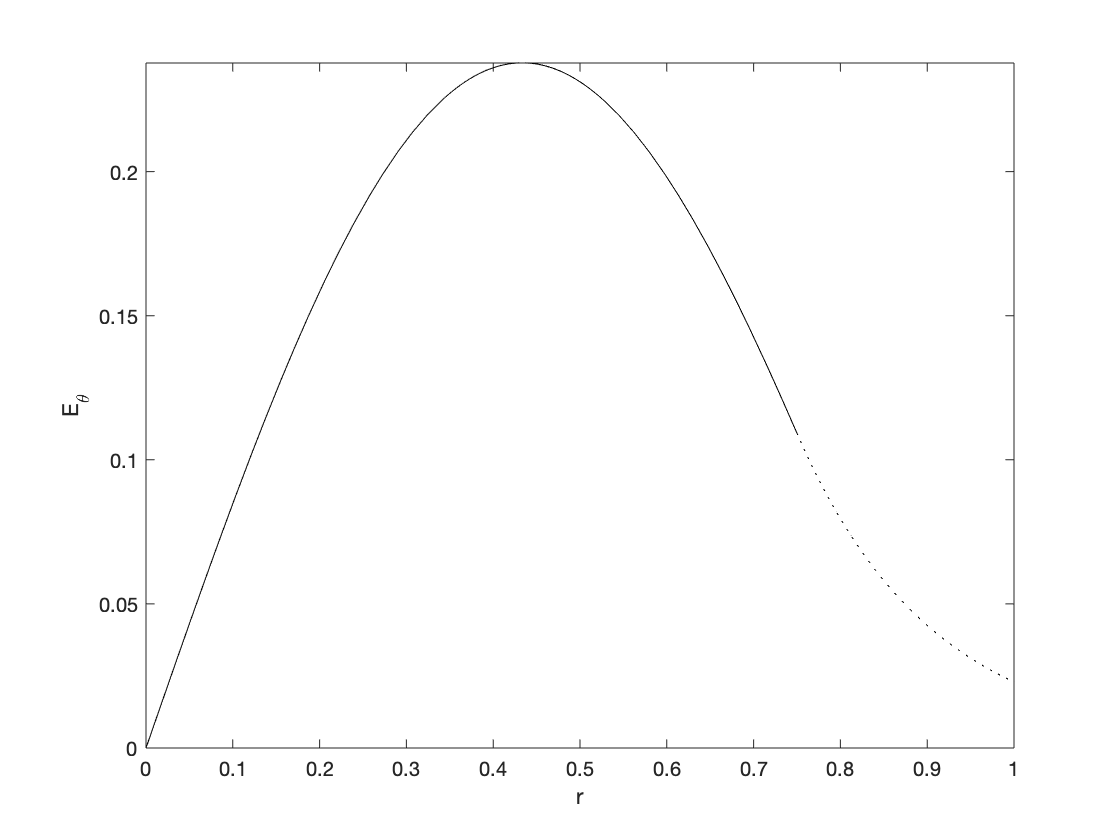

figure;
fplot(subs(E_theta_1,[x,t],[1/2,1/8]),[0,a],'k-'); hold on;
fplot(subs(E_theta_2,[x,t],[1/2,1/8]),[a,1],'k:'); xlabel('r'); ylabel('E_\theta');

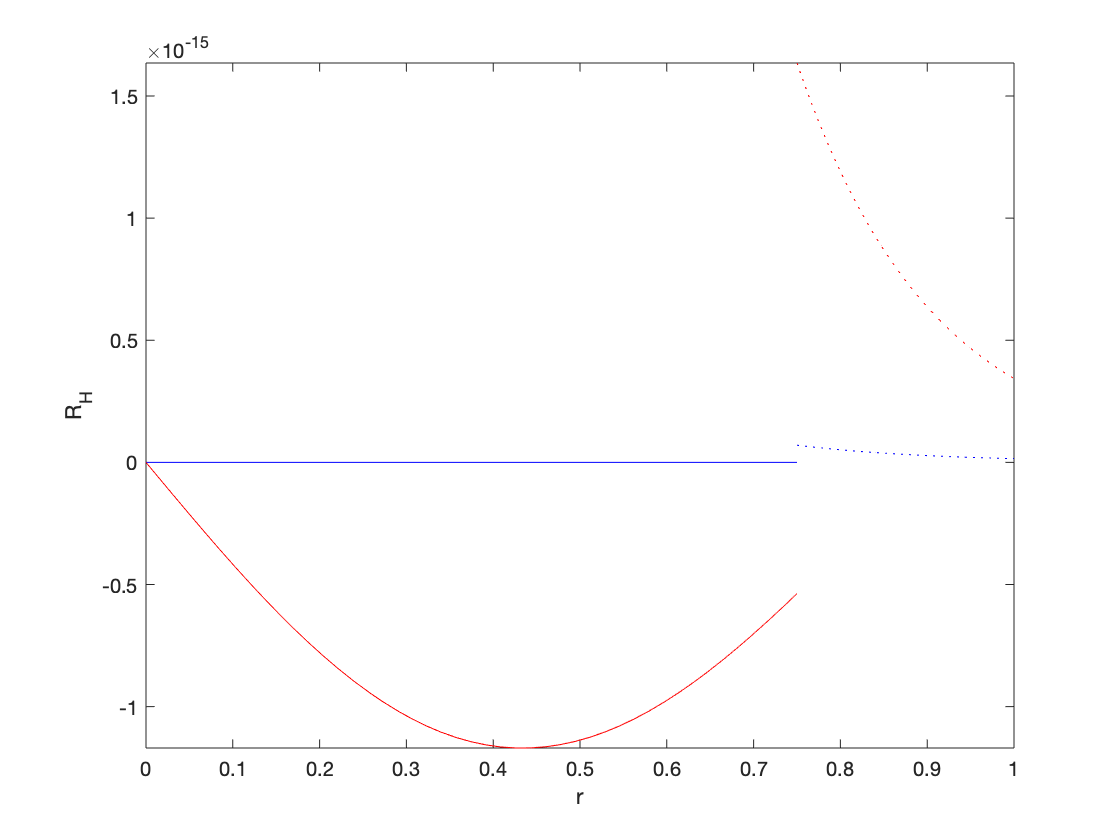


% Change of coordinates (valid for y>0 only)
X=[x;y];
r=y;
H_1=[eval(H_x_1);eval(H_r_1)];
H_2=[eval(H_x_2);eval(H_r_2)];
E_1=eval(E_theta_1);
E_2=eval(E_theta_2);

% Check residuals
R_H_1=simplify(       mu*diff(H_1,t)+mycurl(E_1,X)+[1/y*E_1;0]);
R_H_2=simplify(       mu*diff(H_2,t)+mycurl(E_2,X)+[1/y*E_2;0]);
R_E_1=simplify(epsilon_1*diff(E_1,t)-mycurl(H_1,X));
R_E_2=simplify(epsilon_2*diff(E_2,t)-mycurl(H_2,X));

% Plot
figure; colororder({'b','r','b','r'});
fplot(subs(R_H_1,[x,t],[1/2,1/8]),[0,a],'-'); hold on;
fplot(subs(R_H_2,[x,t],[1/2,1/8]),[a,1],':'); xlabel('r'); ylabel('R_H');

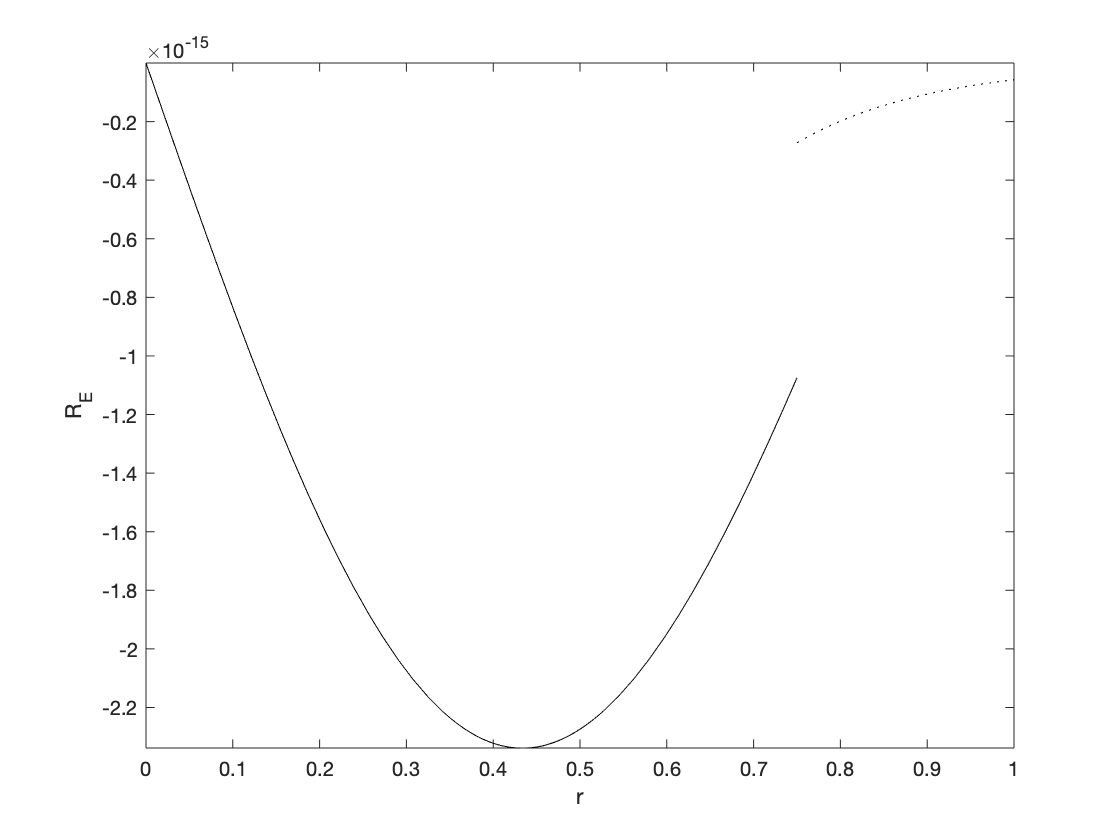

figure;
fplot(subs(R_E_1,[x,t],[1/2,1/8]),[0,a],'k-'); hold on;
fplot(subs(R_E_2,[x,t],[1/2,1/8]),[a,1],'k:'); xlabel('r'); ylabel('R_E');


% Interface variations
H_ratio=eval(subs(H_1./H_2,y,a))

H_ratio =      1
     1


E_ratio=eval(subs(E_1./E_2,y,a))

E_ratio = 1